# Exercise 4.7: First Order

## Visualize Analytical Solution

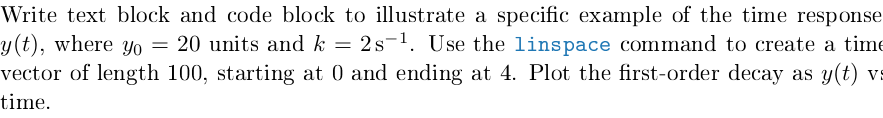

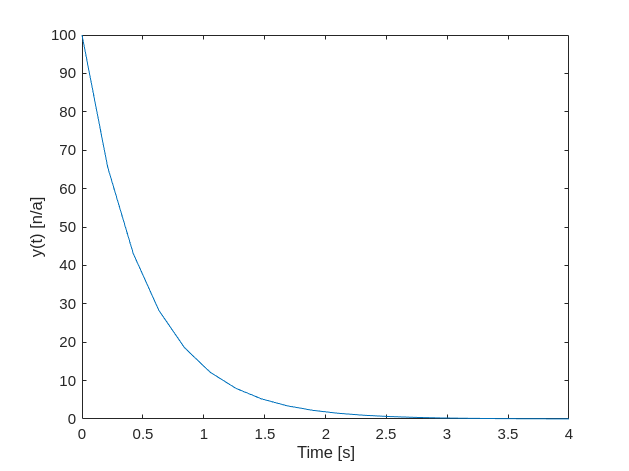

y0 = 100;
k = 2;
tt = linspace(0,4,20);
yy = y0*exp(-k*tt);
figure(1);
clf;
plot(tt,yy)
ylabel('y(t) [n/a]')
xlabel('Time [s]')

Note that we don't need a loop here.  MATLAB arithmetic work well with vectors.

## Numerical Solution: Implement Difference Equation

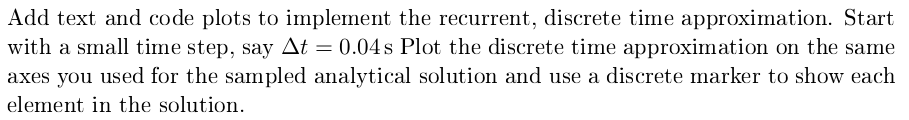

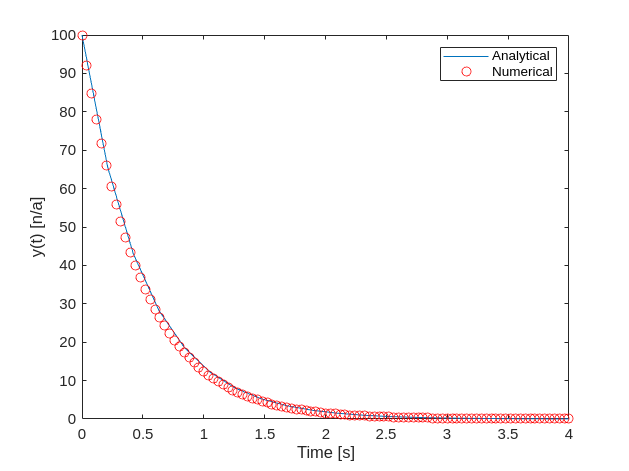

y2(1) = y0;
dt = 0.04;
tt2 = 0:dt:4;
for ii = 2:length(tt2)
    y2(ii) = (1-k*dt)*y2(ii-1);
end
hold on
plot(tt2,y2,'ro');
legend('Analytical', 'Numerical')

## Experiment with timesteps

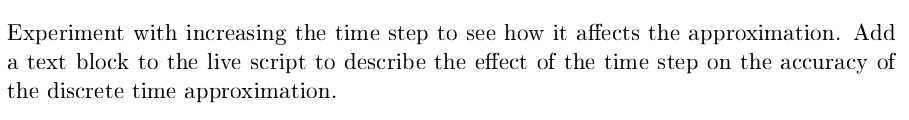

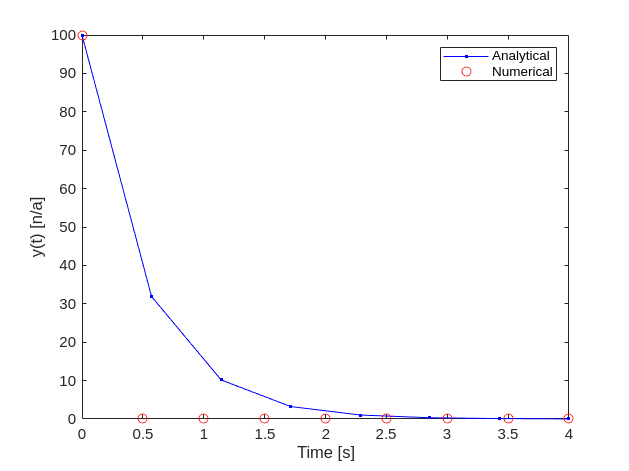

clear
dt = 0.5;
y0 = 100;
k = 2;
% Analytical
tt = linspace(0,4,round(4/dt));
yy = y0*exp(-k*tt);
% Numerical
tt2 = 0:dt:4;
clear y2;
y2(1) = y0;
for ii = 2:length(tt2)
    y2(ii) = (1-k*dt)*y2(ii-1);
end
% Plot
figure;
clf();
plot(tt,yy,'b.-')
hold on
plot(tt2,y2,'ro');
legend('Analytical', 'Numerical')
ylabel('y(t) [n/a]')
xlabel('Time [s]')

In particular, we see that the when the time step is great than about 0.1 there is a significant difference between the two solutions.

And it gets much worse when dt is great than 0.4.

But this answer depends on the value of $k
$.

In general, we need to consider the *time constantt,*


$$\tau = 1/k = 0.25 \, s$$


In general, the time step needs to be much smaller than the time constant: $\Delta t <<\tau$